# Auslegung einer Traktionsbatterie für Bahnstrecken

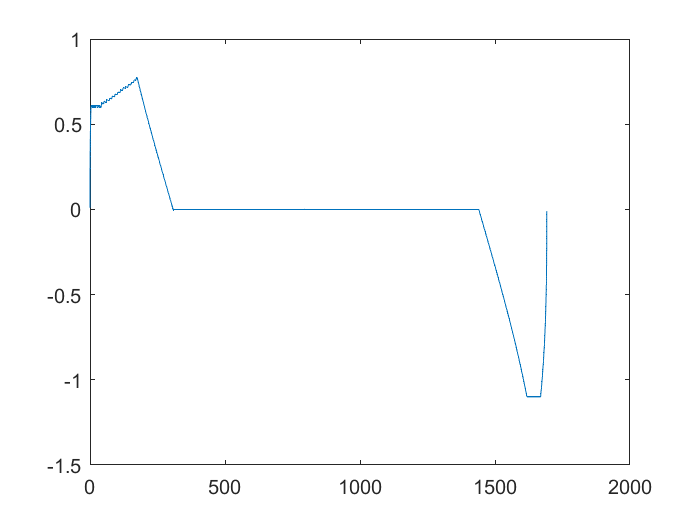

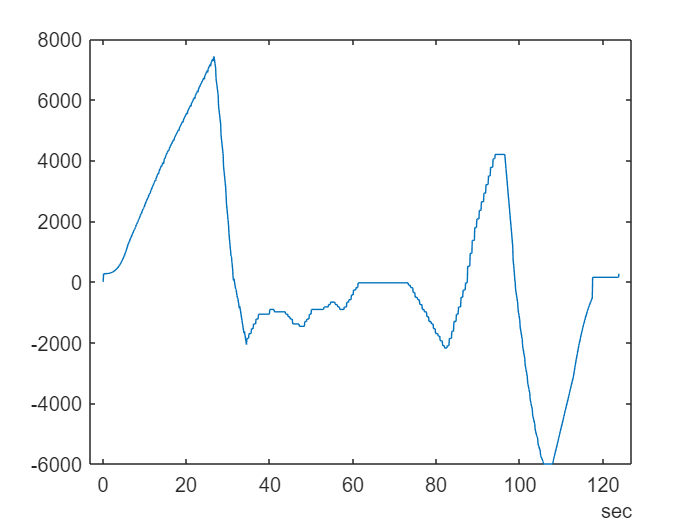

% Dieses Skript dient dazu, Traktionsbatterien für Bahnstrecken, auf
% Grundlage einer Fahrtsimulation der Strecke, auszulegen. 
cla reset
% Eingabe, welcher Prozentsatz der Leistung gedeckt werden soll: 
% (CR = cover ratio)
CR = input("Geben Sie den gewünschten Deckungsgrad in % ein: "); % Cover Ratio in %

% Zunächst werden die benötigten Inputs der Strecken und des gewünschten
% Fahrzeuges geladen:
Streckenparameter2;
Import_track_ZLR_Data;

% Eingabe der gewünschten Strecke:
Str = input("Geben Sie die gewünschte Strecke ein: "); % ST_ZH, HB_ZH, ZH_HB, ZH_ST

% Eingabe des gewünschten Fahrzeuges: 
FZ = input("Geben Sie den gewünschten Zugtypen ein: "); % KISS, RE450 etc.

% Eingabe der Fahrtzeit: (Diese sollte ungefähr der realen Fahrtzeit
% entsprechen (2 oder 3 min oder mit Verspätung < 2min)
Fahrtzeit = input("Geben Sie die gewünschte Fahrtzeit in Sekunden ein: "); % [s] Fahrtzeit kann manuell angepasst werden


% Benötigte Berechnungen für Geschw. und Bremspunkte werden berechent für
% die Strecke
Optimization4;

% Durchführung der Simulation
SimulationAuslegungTraktionsbatterie;

## Berechnung der Leistung um CR einzusparen: Kontinuierlicher Ansatz

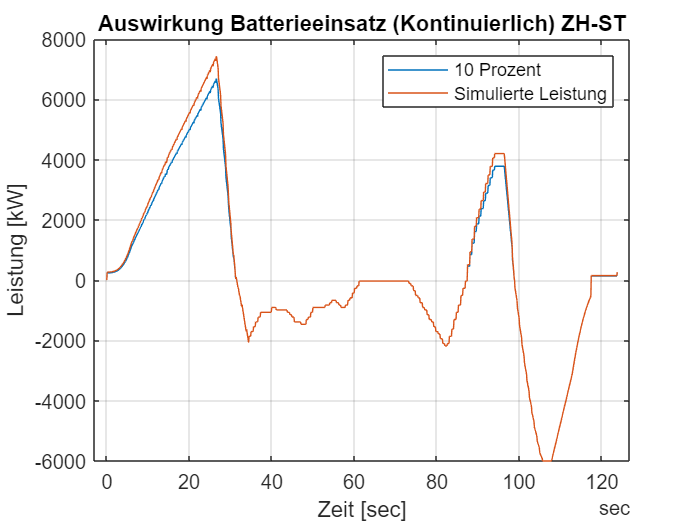

cla reset
% Es wird die neue Leistungskurve mit dem festgesetzten Prozentsatz an zu
% deckender Leistung berechnet
for i = 1:length(CompData.Leistung)
    % Da hier während der Simulation nicht geladen wird, nur
    % Batteriegebrauch wenn positive Leistung ansteht.
    if (CompData.Leistung(i) > 0)
        P(i,1) = CR/100 * CompData.Leistung(i); % Berechnung der Batterieleistung zu jedem Zeitpunkt
        P(i,2) = CompData.Leistung(i) - P(i,1); % Berechnung der übrigen Leistung
    else
        P(i,1) = 0;
        P(i,2) = CompData.Leistung(i);
    end
end

% Plotten des alten gegenüber dem neuen, durch Batterieeinsatz reduzierten,
% Leistungsverlauf.
plot(CompData.time, P(:,2), CompData.time, CompData.Leistung)
title('Auswirkung Batterieeinsatz (Kontinuierlich) ZH-ST')
xlabel('Zeit [sec]')
ylabel('Leistung [kW]')
legend(string(CR) + " Prozent", 'Simulierte Leistung')
grid()


% Das maximum der Differenz der beiden Kennlinien kann verwendet werden, um
% die maximale Leistung, welche für die Deckung benötigt wird zu bestimmen.
PDiff = CompData.Leistung - P(:,2);
PBatCont = max(P(:,1));

% Die Differenz der Energie beider Kennlinien wird verwendet, um die
% Kapazität der Batterie zu bestimmen.
EBatContTOT = cumsum(const.dt * P(:,1));
EBatCont = sum(const.dt * P(:,1))

EBatCont = 1.4413e+04

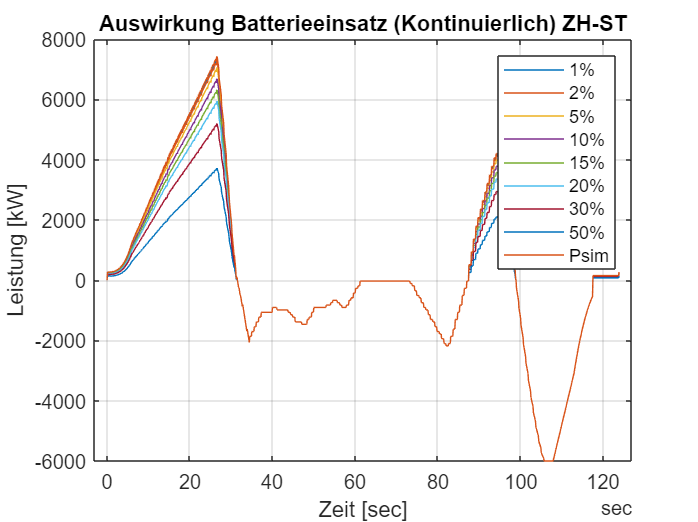


% Es werden automatisch verschiedene Prozentsätze berechnet und danach
% miteinander verglichen.
%CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.25, 0.3, 0.35, 0.4, 0.45, 0.5]; % zu berechnende Prozentsätze
CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.3, 0.5];

for n = 1:length(CRset)
    for i = 1:length(CompData.Leistung)
        if (CompData.Leistung(i) > 0)
            P(i,n) = CRset(n) * CompData.Leistung(i); % Berechnung der benötigten Batterieleistung zu jedem Zeitpunkt
            Psub(i,n) = CompData.Leistung(i) - P(i,n); % Berechnung der verbleibenden Leistung, welche vom Netz kommen muss
        else
            P(i,n) = 0; % Es wird keine Leistung von der Batterie bezogen, wenn die Leistung negativ ist (bergab oder ähnliches)
            Psub(i,n) = CompData.Leistung(i); % Die Leistung bleibt dieselbe
        end
    end
    PDiff(:,n) = CompData.Leistung - Psub(:,n); % Die Differenz der ursprünglichen Leistung und der verbleibenden Leistung ergibt die Batterieleistung
    PBatCont(:,n) = max(PDiff(:,n)); % Die für jeden Deckungsgrad benötigte max. Batterieleistung wird berechnet.
    EBatContTOT(:,n) = cumsum(const.dt * P(:,n)); % Berechnung des kumulierten Verlaufes der benötigten Austauschenergie
    EBatCont(n) = sum(const.dt * P(:,n)); % die benötigte Kapazität für jeden Deckungsgrad ist die Summe der Batterieleistungen
end
    
% Darstellung der neuen Leistungsverläufe mit den Auswirkungen der Batterie
plot(CompData.time, Psub(:,:), CompData.time, CompData.Leistung)
legendString = [string(CRset * 100) + "%" "Psim"];
legend(legendString)
ylabel('Leistung [kW]')
xlabel('Zeit [sec]')
title('Auswirkung Batterieeinsatz (Kontinuierlich) ZH-ST')
grid()

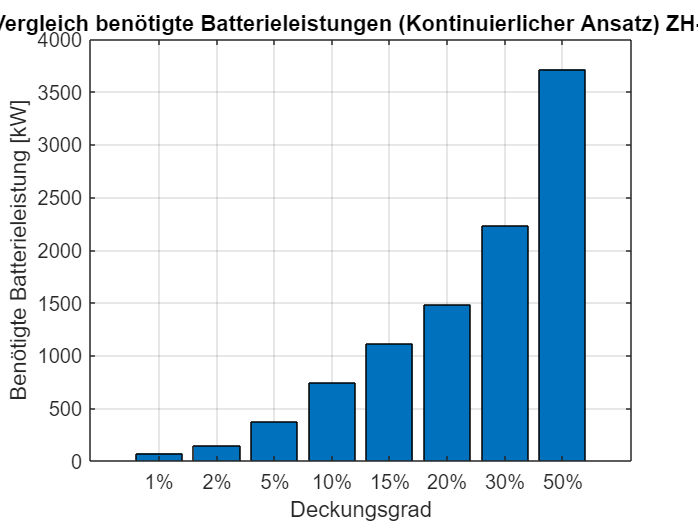


% Darstellung der benötigten Batterieleistungen für das Erreichen der
% Einsparungen
bar(PBatCont)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batterieleistung [kW]")
xlabel('Deckungsgrad')
title('Vergleich benötigte Batterieleistungen (Kontinuierlicher Ansatz) ZH-ST')
grid()

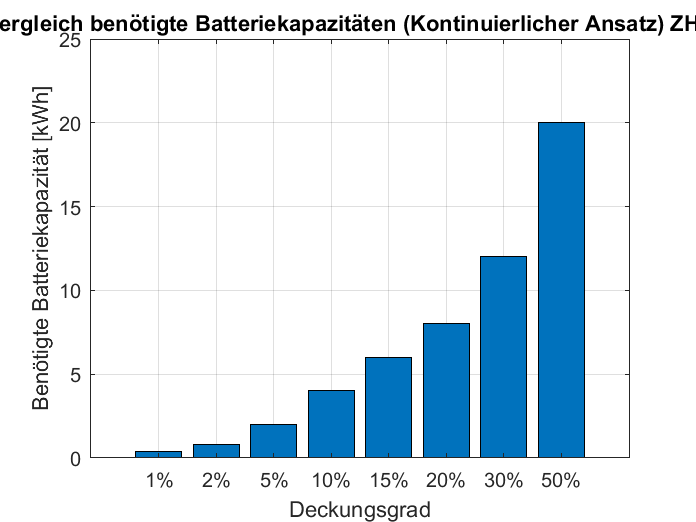


% Darstellung der benötigten Batteriekapazität (Energie)
bar(EBatCont/1000/3.6)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batteriekapazität [kWh]")
xlabel('Deckungsgrad')
title('Vergleich benötigte Batteriekapazitäten (Kontinuierlicher Ansatz) ZH-ST')
grid()


% Darstellung des Energieverlaufes (bezogene Energie aus der Batterie in
% Abhängigkeit der Zeit:
plot(CompData.time, EBatContTOT(:,:)/3600)
legend(legendString)

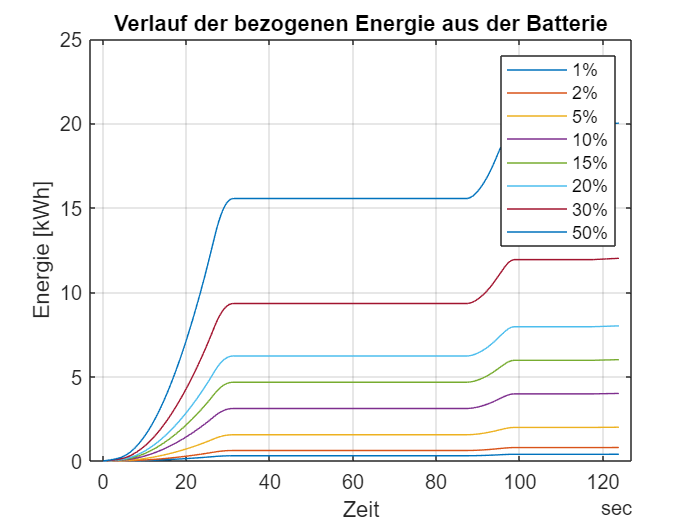

ylabel('Energie [kWh]')
xlabel('Zeit')
title('Verlauf der bezogenen Energie aus der Batterie')
grid()

## Berechnung der Leistung um CR einzusparen: Spitzendeckender Ansatz

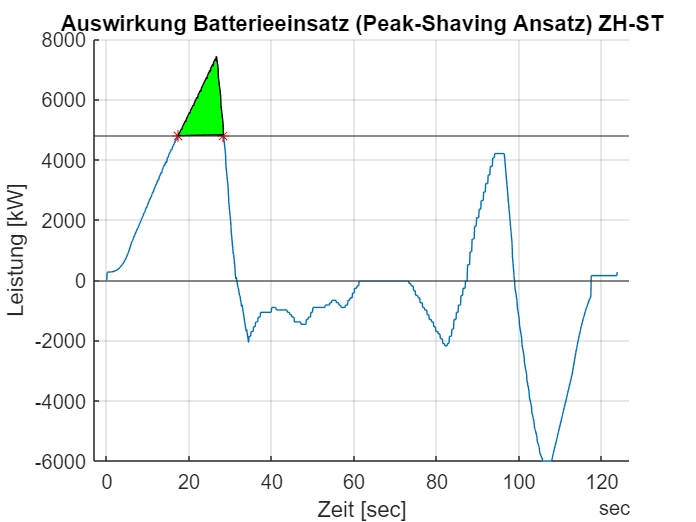

cla reset
% Berechnung der Gesamtfläche:
% Es wird das Matlab Package "Fast and Robust Curve Intersections" von
% Douglas Schwarz benötigt, um die Schnittpunkte zu finden.

% Es wird die Gesamtenergie berechnet, welche der Zug bei positiver
% Leistung benötigt.
for i = 1:length(CompData.Strecke)
    if (CompData.Leistung(i) > 0)
        Etot(i,1) = CompData.Energie(i);
    else
        Etot(i,1) = 0;
    end
end
ETOT = sum(Etot);

% Es wird eine frei gewählter Startpunkt für den ersten Schnittpunkt
% gewählt.
inters = max(CompData.Leistung)-10; % the intersection line

% Nun wird der Schnittpunkt so lange nach unten verschoben, bis der
% energetische Deckungsgrad, welcher festgelegt wurde, erreicht ist.
% Das heisst, dass z.B. bei 10% auch 10% der Energie nun durch die Batterie
% gedeckt werden.
EBatPeak = 0;
while (ETOT * CR/100 > EBatPeak)
    EBatPeak = 0; % Die Kapazität wird auf 0 gesetzt.
    inters = inters - 1; % Der Schnittpunkt wird verschoben
    % Die Schnittpunkte werden gesucht.
    [xlin, ylin] = intersections(1:length(CompData.Leistung),CompData.Leistung, [1, length(CompData.Leistung)], [inters inters]);
    xlin = round(xlin);

    if(length(xlin) > 2) % Wenn es mehr als zwei Schnittpunkte mit der Leistungskurve gibt.

        for i = 1:2:length(xlin)

            EBatPeak = EBatPeak + sum(CompData.Leistung(xlin(i):xlin(i+1))-inters)*const.dt;
            % Die benötigte Batterieleistung entspricht der Summe der
            % Flächen zwischen der Schnittpunktlinie und dem Leistungsverlauf

        end
    else
        EBatPeak = sum(CompData.Leistung(xlin(1):xlin(2))-inters)*const.dt;
        % Die benötigte Batterieleistung entspricht der Summe der
        % Flächen zwischen der Schnittpunktlinie und dem Leistungsverlauf
    end

    if (ETOT * CR/100 < 0.999 * EBatPeak)
        % Wenn die Batteriekapazität zu hoch wird, wird der Schnittpunkt
        % noch einmal korrigiert.
        inters = inters + 1.5;
        EBatPeak = 0;
    end

end

% Darstellung des Leistungsverlaufes mit den Schnittpunkten und den von der
% Batterie gedeckten Flächen (Energie) für den spez. Deckungsgrad (CR)
hold on
plot(CompData.time, CompData.Leistung)
for i = 1:2:length(xlin)
    plot(CompData.time(xlin(i)),ylin(i),'r*', CompData.time(xlin(i+1)), ylin(i+1),'r*')
    fill(CompData.time(xlin(i):xlin(i+1)), CompData.Leistung(xlin(i):xlin(i+1)), 'g')
end
yline(inters)
yline(0)
title('Auswirkung Batterieeinsatz (Peak-Shaving Ansatz) ZH-ST')
xlabel('Zeit [sec]')
ylabel('Leistung [kW]')
grid()

cla reset

% Die benötigte Batterieleistung kann nun berechnet werden, um die
% berechnete Leistungsspitze zu decken.
PBatPeak = max(CompData.Leistung) - inters;

% Ebenfalls kann die benötigte Energie, welche für die Deckung benötigt
% wird berechnet werden:
EBatPeak

EBatPeak = 1.4423e+04

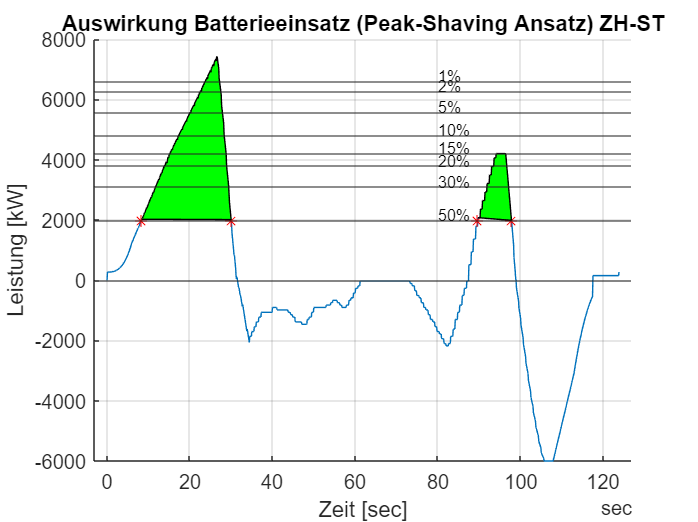


% Es werden automatisch verschiedene Prozentsätze berechnet und danach
% miteinander verglichen.
%CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.25, 0.3, 0.35, 0.4, 0.45, 0.5]; % zu berechnende Prozentsätze
CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.3, 0.5];

inters(1:length(CRset)) = max(CompData.Leistung)-10;

EBatPeak(1:length(CRset)) = 0;

% Dasselbe Vorgehen wie bei einem einzelnen Deckungsgrad wird verwendet,
% wobei hier noch über alle gesetzten Deckungsgrade ein loop gemacht wird.
for n = 1:length(CRset)
    EBatPeak(n) = 0;

    while (ETOT * CRset(n) > EBatPeak(n))
        EBatPeak(n) = 0;
        inters(n) = inters(n) - 1;
        [xlin, ylin] = intersections(1:length(CompData.Leistung),CompData.Leistung, [1, length(CompData.Leistung)], [inters(n) inters(n)]);
        xlin = round(xlin);

        if(length(xlin) > 2)

            for i = 1:2:length(xlin)

                EBatPeak(n) = EBatPeak(n) + sum(CompData.Leistung(xlin(i):xlin(i+1))-inters(n))*const.dt;

            end
            
        else
            EBatPeak(n) = sum(CompData.Leistung(xlin(1):xlin(2))-inters(n))*const.dt;
        end

        PBatPeak(n) = max(CompData.Leistung) - inters(n);
   
    end
end

for n = 1:length(CRset)
    for i = 1:length(CompData.Leistung)
        if (CompData.Leistung(i) > inters(n))
            PBatPeakTOT(i,n) = CompData.Leistung(i) - inters(n);
        else 
            PBatPeakTOT(i,n) = 0;
        end
    end
end
EBatPeakTOT = cumsum(const.dt * PBatPeakTOT);

% Darstellung des Leistungsverlaufes mit den Schnittpunkten und den von der
% Batterie gedeckten Flächen (Energie) für die festgesetzten Deckungsgrade (CRset)
hold on
plot(CompData.time, CompData.Leistung)
for i = 1:2:length(xlin)
    plot(CompData.time(xlin(i)),ylin(i),'r*', CompData.time(xlin(i+1)), ylin(i+1),'r*')
    fill(CompData.time(xlin(i):xlin(i+1)), CompData.Leistung(xlin(i):xlin(i+1)), 'g')
end
yline(inters)
yline(0)
grid()
text(ones(length(inters),1)*80 , inters + 180, [string(CRset * 100) + "%"],"FontSize",8)
title('Auswirkung Batterieeinsatz (Peak-Shaving Ansatz) ZH-ST')
xlabel('Zeit [sec]')
ylabel('Leistung [kW]')

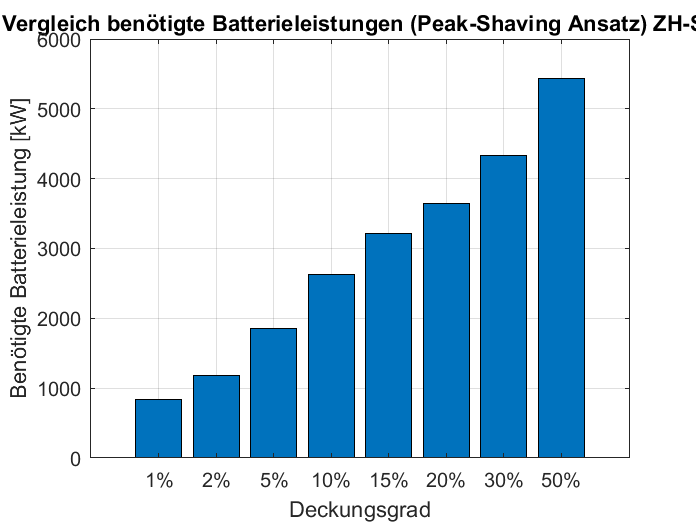

cla reset

% Darstellung der benötigten Batterieleistungen für das Erreichen der
% Einsparungen
bar(PBatPeak)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batterieleistung [kW]")
xlabel('Deckungsgrad')
title('Vergleich benötigte Batterieleistungen (Peak-Shaving Ansatz) ZH-ST')
grid()

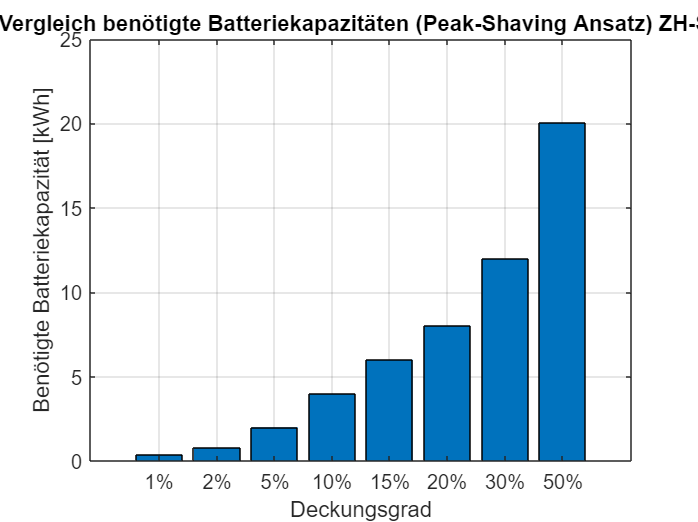


% Darstellung der benötigten Batteriekapazität (Energie)
bar(EBatPeak/1000/3.6)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batteriekapazität [kWh]")
xlabel('Deckungsgrad')
title('Vergleich benötigte Batteriekapazitäten (Peak-Shaving Ansatz) ZH-ST')
grid()


% Darstellung der Verläufe der ausgetauschten Energie mit der Batterie
plot(CompData.time, EBatPeakTOT(:,:)/3600)
ylabel('Ausgetauschte Energie [kWh]')
xlabel('Zeit [s]')
title('Ausgetauschte Energie mit der Batterie im Verlaufe der Fahrt (Peak-Shaving Ansatz) ZH-ST')
legend(legendString)

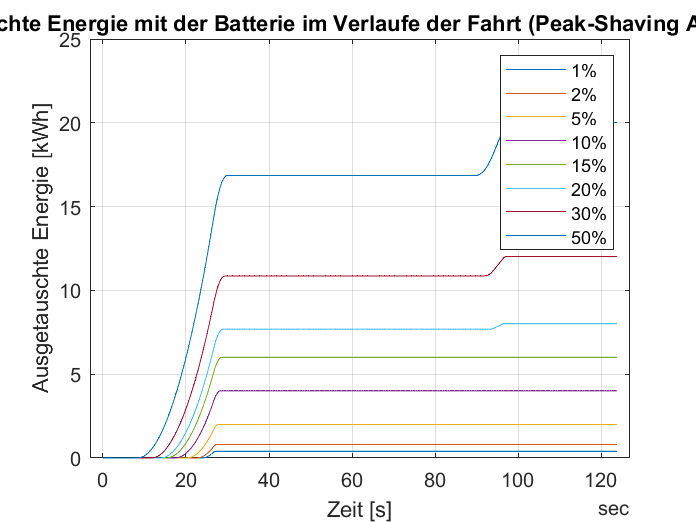

grid()



% load('BatterieAuslegung')
% 
% BatteryDimensions.(Str.id).CRset = CRset;
% BatteryDimensions.(Str.id).EBatCont = EBatCont;
% BatteryDimensions.(Str.id).EBatPeak = EBatPeak;
% BatteryDimensions.(Str.id).ETOT = ETOT;
% BatteryDimensions.(Str.id).inters = inters;
% BatteryDimensions.(Str.id).PBatCont = PBatCont;
% BatteryDimensions.(Str.id).Psub = Psub;
% BatteryDimensions.(Str.id).PBatPeak = PBatPeak;
% 
% save('BatterieAuslegung', 'BatteryDimensions')

% load('BatterieAuslegung2')
% for i = 1:length(CRset)
%     BD.(Str.id).("CR_" + string(CRset(i)*100) + "_Prozent").EBatCont = EBatCont(i);
%     BD.(Str.id).("CR_" + string(CRset(i)*100) + "_Prozent").EBatPeak = EBatPeak(i);
%     BD.(Str.id).("CR_" + string(CRset(i)*100) + "_Prozent").ETOT = ETOT;
%     BD.(Str.id).("CR_" + string(CRset(i)*100) + "_Prozent").inters = inters(i);
%     BD.(Str.id).("CR_" + string(CRset(i)*100) + "_Prozent").PBatCont = PBatCont(i);
%     BD.(Str.id).("CR_" + string(CRset(i)*100) + "_Prozent").Psub = Psub(:,i);
%     BD.(Str.id).("CR_" + string(CRset(i)*100) + "_Prozent").PDiff = PDiff(:,i);
%     BD.(Str.id).("CR_" + string(CRset(i)*100) + "_Prozent").PBatPeak = PBatPeak(i);
%     BD.(Str.id).("CR_" + string(CRset(i)*100) + "_Prozent").CompData = CompData;
% end
% save('BatterieAuslegung2', 'BD')



## Speichern der Daten


% Speichern der Simulationsdaten in einer Tabelle für die
% Weiterverarbeitung:
load('BatterieTabelleDoppelt');
CRset = CRset(:); EBatCont = EBatCont(:); EBatPeak = EBatPeak(:); inters = inters(:); PBatCont = PBatCont(:); PBatPeak = PBatPeak(:);
%BD.(Str.id) = table(CRset.', EBatCont.', EBatPeak.', inters.', PBatCont.', PBatPeak.');
% BD = BatteryDimension
BD.(Str.id).BatTable = table(CRset, EBatCont, EBatPeak, inters, PBatCont, PBatPeak);
BD.(Str.id).EBatContTOT = EBatContTOT;
BD.(Str.id).EBatPeakTOT = EBatPeakTOT;
BD.(Str.id).PBatPeakTOT = PBatPeakTOT;
BD.(Str.id).CompData = CompData;

save('BatterieTabelleDoppelt', 'BD');





## Simulation der Batterie, wenn diese geladen wird (Kontinuierlich)

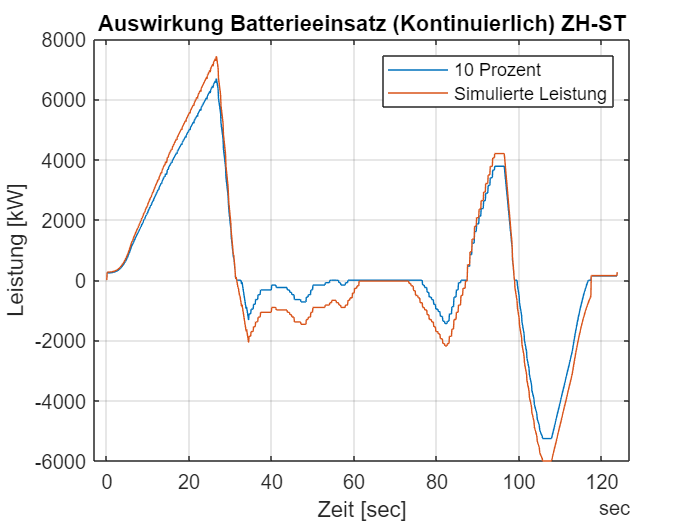

% Es werden erneut die beiden Szenarien berechnet, jedoch soll nun die
% Batterie bei negativer Leistung geladen werden. Dadurch wird die Energie
% nicht mehr ins Netz zurückgegeben, sondern intern für das Laden der
% Batterie verwendet.

% Kontinuierlicher Ansatz:
cla reset

% Es wird die neue Leistungskurve mit dem festgesetzten Prozentsatz an zu
% deckender Leistung berechnet
PBatMax = CR/100 * max(CompData.Leistung); % Berechnung der max. Batterieleistung für die Deckung von CR 
for i = 1:length(CompData.Leistung)
    % Nun wird nicht mehr nur Energie mit der Batterie ausgetauscht, wenn
    % die Leistung positiv ist, sondern auch bei negativer Leistung
    % --> Entladen bei positiver und laden bei negativer Leistung
    if (CompData.Leistung(i) > 0)
        P(i,1) = CR/100 * CompData.Leistung(i); % Die Batterieleistung wird zu jedem Zeitpunkt berechnet
        P(i,2) = CompData.Leistung(i) - P(i,1); % Die übrig bleibende Leistung die vom Netz bezogen wird
    elseif (CompData.Leistung(i) < 0 && abs(CompData.Leistung(i)) <= PBatMax)
        % Wenn die Leistung negativ ist und kleiner ist als die maximale
        % Batterieleistung 
        P(i,1) = CompData.Leistung(i); % Die Leistung der Batterie (laden) entspricht dem Leistungsverlauf
        P(i,2) = 0; % die übrig bleibende Leistung ist 0.
    elseif (CompData.Leistung(i) < 0 && abs(CompData.Leistung(i)) > PBatMax)
        % Wenn die Leistung negativ ist und grösser als die max.
        % Batterieleistung
        P(i,1) = -PBatMax; % die Ladeleistung entspricht der maximalen Leistung der Batterie
        P(i,2) = CompData.Leistung(i) + PBatMax; % die übrig bleibende Leistung entspricht der Summe aus Ladeleistung und effektiver Leistung
    end
end

% Das maximum der Differenz der beiden Kennlinien kann verwendet werden, um
% die maximale Leistung, welche für die Deckung benötigt wird zu bestimmen.
PDiff = CompData.Leistung - P(:,2);
PBatCont = max(P(:,1));

% Darstellung des neuen Leistungsverlaufes, wenn Batterie auch geladen
% wird.
plot(CompData.time, P(:,2), CompData.time, CompData.Leistung)
title('Auswirkung Batterieeinsatz (Kontinuierlich) ZH-ST')
xlabel('Zeit [sec]')
ylabel('Leistung [kW]')
legend(string(CR) + " Prozent", 'Simulierte Leistung')
grid()

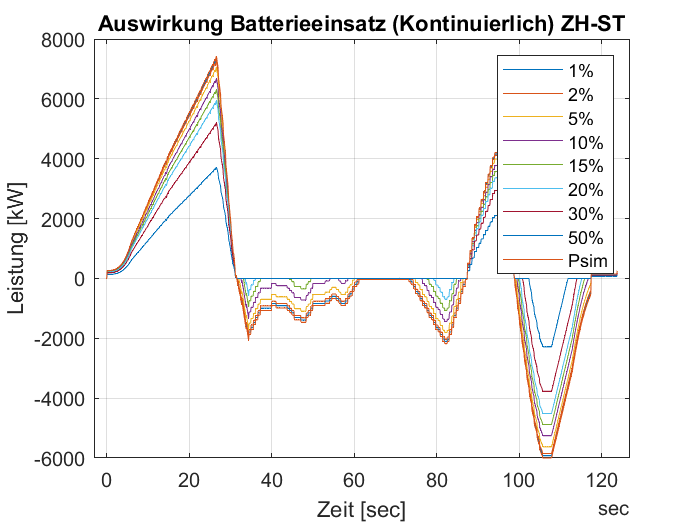


% Die Differenz der Energie beider Kennlinien wird verwendet, um die
% Kapazität der Batterie zu bestimmen.
EBatContReach = const.dt * P(:,1); % Es wird die mit der Batterie ausgetauschte Energie zu jedem Zeitpunkt berechnet.

EBatContReach(:,2) = cumsum(EBatContReach(:,1)); % Die Energie wird kumulativ aufsummiert um einen Verlauf der Batteriekapazität
% darstellen zu können. --> es werden auch die Lade- und Entladevorgänge
% sichtbar.

EBatCont = max(EBatContReach(:,2)) - min(EBatContReach(:,2)); % Hier wird die max. Batteriekapazität berechent.

% Es werden automatisch verschiedene Prozentsätze berechnet und danach
% miteinander verglichen.
%CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.25, 0.3, 0.35, 0.4, 0.45, 0.5]; % zu berechnende Prozentsätze
CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.3, 0.5];
PMax = max(CompData.Leistung); % Berechnung der max. Leistung für die Deckung von CR 

% Es wird ein loop über alle gesetzten Deckungsgrade gemacht.
for n = 1:length(CRset)
    for i = 1:length(CompData.Leistung)
        % Nun wird nicht mehr nur Energie mit der Batterie ausgetauscht, wenn
        % die Leistung positiv ist, sondern auch bei negativer Leistung
        % --> Entladen bei positiver und laden bei negativer Leistung
        if (CompData.Leistung(i) >= 0)
            P(i,n) = CRset(n) * CompData.Leistung(i); % Berechnung der Leistung der Batterie (entladen)
            Psub(i,n) = CompData.Leistung(i) - P(i,n); % Berechnung des verbleibenden Netzbezuges
        elseif (CompData.Leistung(i) < 0 && abs(CompData.Leistung(i)) <= CRset(n) * PMax)
            % Wenn Leistung neg. und kleiner als max. Batterieleistung
            P(i,n) = CompData.Leistung(i); % Batterieleistung (laden) entspricht der simulierten Leistung
            Psub(i,n) = 0; % kein Netzbezug
        elseif (CompData.Leistung(i) < 0 && abs(CompData.Leistung(i)) > CRset(n) * PMax)
            % Wenn Leistung neg. und grösser als max. Batterieleistung
            P(i,n) = -CRset(n) * PMax; % Ladeleistung = maximale Batterieleistung
            Psub(i,n) = CompData.Leistung(i) + CRset(n) * PMax; % es wird immernoch Leistung ins Netz zurückgegeben
        end
        EBatContReach(i,n) = const.dt * P(i,n); % Berechnung der mit der Batterie ausgetauschten Energie zu jedem Zeitpunkt
    end
    PDiff(:,n) = CompData.Leistung - Psub(:,n); % Berechnung der Differenz zwischen Leistung und Netzaustausch
    PBatCont(:,n) = max(P(:,n)); % Berechnung der maximalen Batterieleistung.      
end

% Verwenden der Funktion cumsum um die benötigte Energie aufzuaddieren.
EBatContReachTOT = cumsum(EBatContReach); % Energie wird kumuliert um den Verlauf des Austausches darstellen zu können.
for i = 1:length(CRset)
    EBatCont(1,i) = max(EBatContReachTOT(:,i)) - min(EBatContReachTOT(:,i)); % Berechnen der maximal benötigten Batteriekapazität
end
    
% Darstellung der neuen Leistungsverläufe
plot(CompData.time, Psub(:,:), CompData.time, CompData.Leistung)
legendString = [string(CRset * 100) + "%" "Psim"];
legend(legendString)
ylabel('Leistung [kW]')
xlabel('Zeit [sec]')
title('Auswirkung Batterieeinsatz (Kontinuierlich) ZH-ST')
grid()


% Darstellung der benötigten Batterieleistungen für das Erreichen der
% Einsparungen
bar(PBatCont)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batterieleistung [kW]")
xlabel('Deckungsgrad')
title('Vergleich benötigte Batterieleistungen (Kontinuierlicher Ansatz) ZH-ST')
grid()

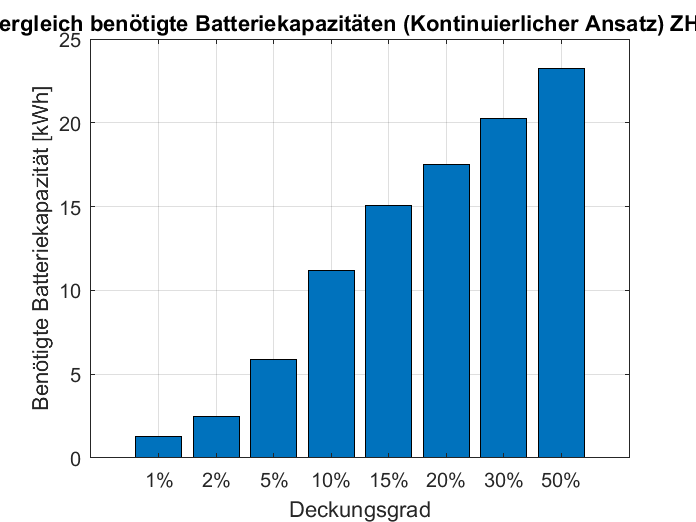


% Darstellung der benötigten Batteriekapazität (Energie)
bar(EBatCont/1000/3.6)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batteriekapazität [kWh]")
xlabel('Deckungsgrad')
title('Vergleich benötigte Batteriekapazitäten (Kontinuierlicher Ansatz) ZH-ST')
grid()


% Darstellung des Batteriestandes während dem Laden und Entladen
plot(CompData.time, EBatContReachTOT(:,:)/3600)
xlabel('Zeit [s]')
ylabel('Ausgetauschte Energie [kWh]')
title('Verlauf des Ladestandes der Batterie auf der Strecke: ' + Str.id)
legend(legendString)

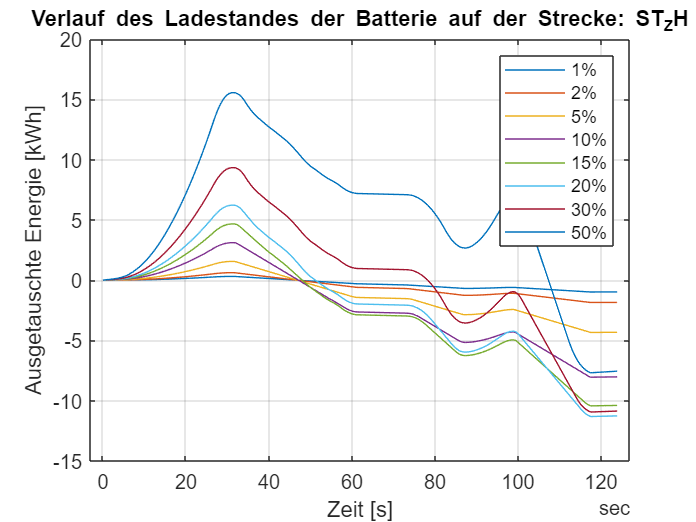

grid()

## Simulation der Batterie, wenn diese geladen wird (peak-shaving)

cla reset
% Berechnung der Gesamtfläche:
% Es wird das Matlab Package "Fast and Robust Curve Intersections" von
% Douglas Schwarz benötigt.

for i = 1:length(CompData.Strecke)
    if (CompData.Leistung(i) > 0)
        Etot(i,1) = CompData.Energie(i);
    else
        Etot(i,1) = 0;
    end
end
ETOT = sum(Etot);

inters = max(CompData.Leistung)-10; % the intersection line

EBatPeak = 0; % setze Batteriekapazität auf 0

% Nun wird der Schnittpunkt so lange nach unten verschoben, bis der
% energetische Deckungsgrad, welcher festgelegt wurde, erreicht ist.
% Das heisst, dass z.B. bei 10% auch 10% der Energie nun durch die Batterie
% gedeckt werden.
while (ETOT * CR/100 > EBatPeak)
    EBatPeak = 0;
    inters = inters - 1; % der Schnittpunkt wird nach unten verschoben
    [xlin, ylin] = intersections(1:length(CompData.Leistung),CompData.Leistung, [1, length(CompData.Leistung)], [inters inters]);
    xlin = round(xlin);
    % die Schnittpunkte werden gesucht und gefunden. Es können mehr als
    % zwei Schnittpunkte sein.

    if(length(xlin) > 2) % Wenn es mehr als zwei SChnittpunkte gibt

        for i = 1:2:length(xlin)

            EBatPeak = EBatPeak + sum(CompData.Leistung(xlin(i):xlin(i+1))-inters)*const.dt;
            % Die benötigte Batterieleistung entspricht der Summe der
            % Flächen zwischen der Schnittpunktlinie und dem Leistungsverlauf

        end
    else % Wenn nur zwei Schnittpunkte gefunden wurden.
        EBatPeak = sum(CompData.Leistung(xlin(1):xlin(2))-inters)*const.dt;
        % Die benötigte Batterieleistung entspricht der Summe der
        % Flächen zwischen der Schnittpunktlinie und dem Leistungsverlauf
    end

    if (ETOT * CR/100 < 0.999 * EBatPeak)
        % Wenn die Batteriekapazität zu hoch wird, wird der Schnittpunkt
        % noch einmal korrigiert.
        inters = inters + 1.5;
        EBatPeak = 0;
    end

end

% Die benötigte Batterieleistung kann nun berechnet werden, um die
% berechnete Leistungsspitze zu decken.
PBatPeak = max(CompData.Leistung) - inters;

% Ebenfalls kann die benötigte maximale Energie, welche für die Deckung benötigt
% wird berechnet werden:
EBatPeak

EBatPeak = 1.4423e+04

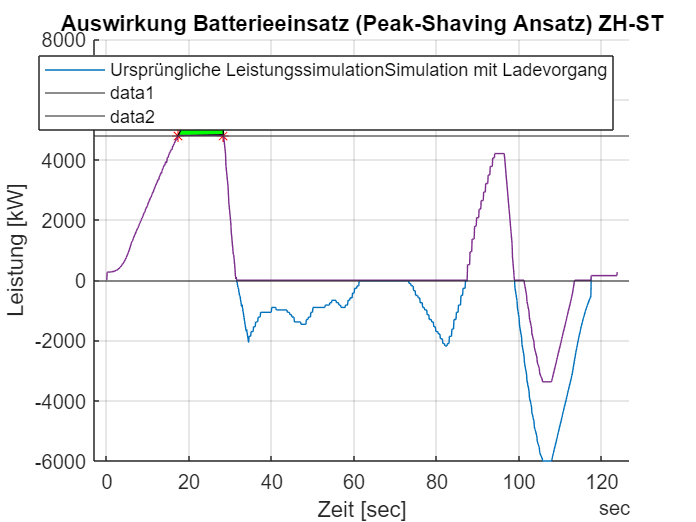


% Nun muss noch das Laden der Batterie integriert werden.
for i = 1:length(CompData.Leistung)
    if (CompData.Leistung(i) < 0 && abs(CompData.Leistung(i)) <= PBatPeak)% && EBatPeak >= abs(EBatNeg))
        % Wenn die Leistung negativ ist und kleiner als die maximale Batterieleistung wird geladen:
        PPeak(i) = 0; %  Die neue Leistung ist 0 da die gesamte Leistung in die Batterie geladen wird
        EBatPeakReach(i,1) = CompData.Leistung(i) * const.dt; % die Ausgetauschte Energie mit der Batterie
    elseif (CompData.Leistung(i) < 0 && abs(CompData.Leistung(i)) > PBatPeak)% && EBatPeak >= abs(EBatNeg))
        % Wenn die Leistung negativ ist und (absolut) grösser als die max. Leistung der Batterie 
        PPeak(i) = CompData.Leistung(i) + PBatPeak; % der neue Netzaustausch wird berechnet
        EBatPeakReach(i,1) = - PBatPeak * const.dt; % Der Energieaustausch mit der Batterie wird berechnet
    elseif (CompData.Leistung(i) >= inters) 
        % Wenn die Leistung grösser ist als der festgelegte Schnittpunkt
        PPeak(i) = inters; % die Ausgetauschte Leistung mit dem Netz (bezug) 
        EBatPeakReach(i,1) = (CompData.Leistung(i)-inters) * const.dt; % Die Energie, welche aus der Batterie bezogen wird
    else
        % Wenn die Leistung positiv ist und unterhalb des festgelegten Schnittpunktes
        PPeak(i) = CompData.Leistung(i); % Der Netzaustausch bleibt derselbe
        EBatPeakReach(i,1) = 0; % Es wird keine Energie mit der Batterie ausgetauscht.
    end
end

% Der kumulierte Energieaustausch mit der Batterie wird berechent
EBatPeakReach(:,2) = cumsum(EBatPeakReach(:,1));

% Die maximale Batteriekapazität wird berechnet.
EBatPeak = max(EBatPeakReach(:,2)) - min(EBatPeakReach(:,2));

% Darstellung der neuen Leistungskennlinie, inklusive Ladevorgang
hold on
plot(CompData.time, CompData.Leistung)
for i = 1:2:length(xlin)
    plot(CompData.time(xlin(i)),ylin(i),'r*', CompData.time(xlin(i+1)), ylin(i+1),'r*')
    fill(CompData.time(xlin(i):xlin(i+1)), CompData.Leistung(xlin(i):xlin(i+1)), 'g')
end
plot(CompData.time, PPeak)
legend(['Ursprüngliche Leistungssimulation' 'Simulation mit Ladevorgang'])
yline(inters)
yline(0)
title('Auswirkung Batterieeinsatz (Peak-Shaving Ansatz) ZH-ST')
xlabel('Zeit [sec]')
ylabel('Leistung [kW]')
grid()

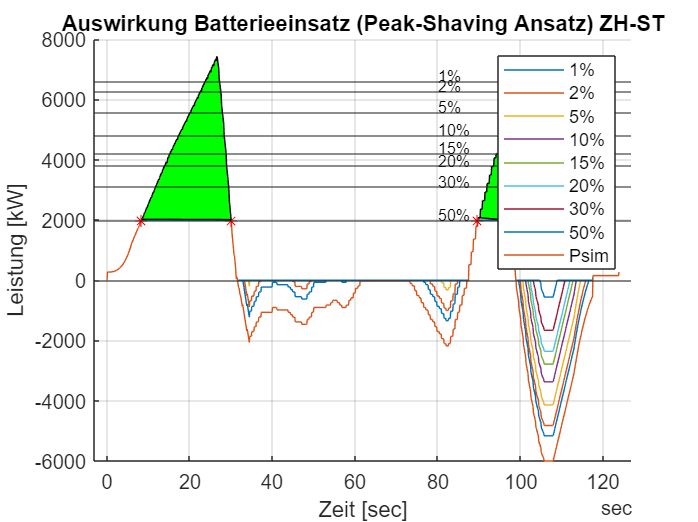

cla reset

% Es werden automatisch verschiedene Prozentsätze berechnet und danach
% miteinander verglichen.
%CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.25, 0.3, 0.35, 0.4, 0.45, 0.5]; % zu berechnende Prozentsätze
CRset = [0.01, 0.02, 0.05, 0.1, 0.15, 0.2, 0.3, 0.5];

inters(1:length(CRset)) = max(CompData.Leistung)-10; % the intersection line

EBatPeak(1:length(CRset)) = 0; % Batteriekapazität auf 0 setzen für alle Deckungsgrade

% Nun wird der Schnittpunkt so lange nach unten verschoben, bis der
% energetische Deckungsgrad, welcher festgelegt wurde, erreicht ist.
% Das heisst, dass z.B. bei 10% auch 10% der Energie nun durch die Batterie
% gedeckt werden.
for n = 1:length(CRset)
    EBatPeak(n) = 0;

    while (ETOT * CRset(n) > EBatPeak(n))
        EBatPeak(n) = 0;
        inters(n) = inters(n) - 1;
        [xlin, ylin] = intersections(1:length(CompData.Leistung),CompData.Leistung, [1, length(CompData.Leistung)], [inters(n) inters(n)]);
        xlin = round(xlin);
        % die Schnittpunkte werden gesucht und gefunden. Es können mehr als
        % zwei Schnittpunkte sein.

        if(length(xlin) > 2)

            for i = 1:2:length(xlin) % Wenn es mehr als zwei SChnittpunkte gibt

                EBatPeak(n) = EBatPeak(n) + sum(CompData.Leistung(xlin(i):xlin(i+1))-inters(n))*const.dt;
                % Die benötigte Batterieleistung entspricht der Summe der
                % Flächen zwischen der Schnittpunktlinie und dem Leistungsverlauf

            end

        else % Wenn nur zwei Schnittpunkte gefunden wurde
            EBatPeak(n) = sum(CompData.Leistung(xlin(1):xlin(2))-inters(n))*const.dt;
            % Die benötigte Batterieleistung entspricht der Summe der
            % Flächen zwischen der Schnittpunktlinie und dem Leistungsverlauf
        end

        PBatPeak(n) = max(CompData.Leistung) - inters(n);
        % Berechnung der maximalen Batterieleistung (entladen) für jeden
        % Deckungsgrad
   
    end
end
PPeak = 0;
% Nun muss noch das Laden der Batterie integriert werden.
for n = 1:length(CRset)
    for i = 1:length(CompData.Leistung)
        if (CompData.Leistung(i) < 0 && abs(CompData.Leistung(i)) <= PBatPeak(n))% && EBatPeak >= abs(EBatNeg))
            % Wenn die Leistung negativ ist und kleiner als die maximale Batterieleistung wird geladen:
            PPeak(i,n) = 0; %  Die neue Leistung ist 0 da die gesamte Leistung in die Batterie geladen wird
            EBatPeakReach(i,n) = CompData.Leistung(i) * const.dt; % die Ausgetauschte Energie mit der Batterie
        elseif (CompData.Leistung(i) < 0 && abs(CompData.Leistung(i)) > PBatPeak(n))% && EBatPeak >= abs(EBatNeg))
            % Wenn die Leistung negativ ist und (absolut) grösser als die max. Leistung der Batterie 
            PPeak(i,n) = CompData.Leistung(i) + PBatPeak(n); % der neue Netzaustausch wird berechnet
            EBatPeakReach(i,n) = - PBatPeak(n) * const.dt; % Der Energieaustausch mit der Batterie wird berechnet
        elseif (CompData.Leistung(i) >= inters(n))
            % Wenn die Leistung grösser ist als der festgelegte Schnittpunkt
            PPeak(i,n) = inters(n); % die Ausgetauschte Leistung mit dem Netz (bezug) 
            EBatPeakReach(i,n) = (CompData.Leistung(i)-inters(n)) * const.dt; % Die Energie, welche aus der Batterie bezogen wird
        else
            % Wenn die Leistung positiv ist und unterhalb des festgelegten Schnittpunktes
            PPeak(i,n) = CompData.Leistung(i); % Der Netzaustausch bleibt derselbe
            EBatPeakReach(i,n) = 0; % Es wird keine Energie mit der Batterie ausgetauscht
        end
    end
end


% Verwenden der Funktion cumsum um die benötigte Energie aufzuaddieren.
% Der kumulierte Energieaustausch mit der Batterie wird berechent
EBatPeakReachTOT = cumsum(EBatPeakReach);

% für jeden Deckungsgrad wird die benötigte Batteriekapazität ermittelt.
for i = 1:length(CRset)
    EBatPeak(1,i) = max(EBatPeakReachTOT(:,i)) - min(EBatPeakReachTOT(:,i));
end

% Darstellung der Leistungsverläufe mit Laden der Batterie
hold on
plot(CompData.time, PPeak(:,:))
plot(CompData.time, CompData.Leistung)
legend(legendString, 'AutoUpdate','off')
for i = 1:2:length(xlin)
    plot(CompData.time(xlin(i)),ylin(i),'r*', CompData.time(xlin(i+1)), ylin(i+1),'r*')
    fill(CompData.time(xlin(i):xlin(i+1)), CompData.Leistung(xlin(i):xlin(i+1)), 'g')
end
yline(inters)
yline(0)
grid()
text(ones(length(inters),1)*80 , inters + 180, [string(CRset * 100) + "%"],"FontSize",8)
title('Auswirkung Batterieeinsatz (Peak-Shaving Ansatz) ZH-ST')
xlabel('Zeit [sec]')
ylabel('Leistung [kW]')

cla reset

% Darstellung der benötigten Batterieleistungen für das Erreichen der
% Einsparungen
bar(PBatPeak)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batterieleistung [kW]")
xlabel('Deckungsgrad')
title('Vergleich benötigte Batterieleistungen (Peak-Shaving Ansatz) ZH-ST')
grid()

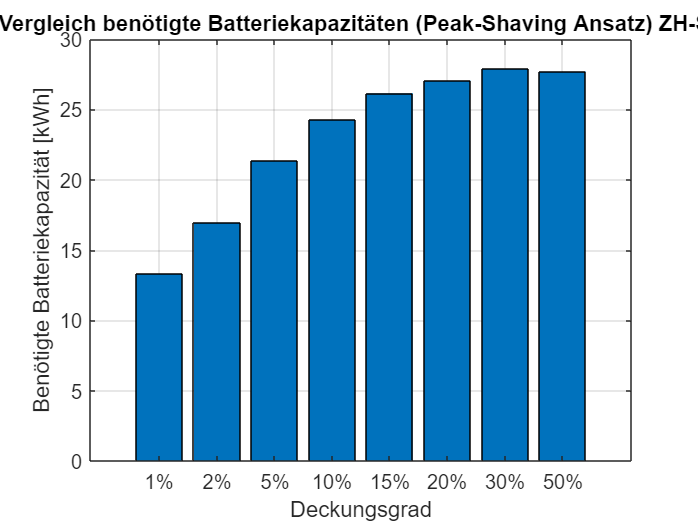


% Darstellung der benötigten Batteriekapazität (Energie)
bar(EBatPeak/1000/3.6)
xticklabels((string(CRset*100) + "%"))
ylabel("Benötigte Batteriekapazität [kWh]")
xlabel('Deckungsgrad')
title('Vergleich benötigte Batteriekapazitäten (Peak-Shaving Ansatz) ZH-ST')
grid()


% Darstellung des Energieaustausches mit der Batterie
plot(CompData.time, EBatPeakReachTOT(:,:)/3600)
ylabel('Energie [kWh]')
xlabel('Zeit [s]')
title('Verlauf des Ladestandes der Batterie auf der Strecke: ' + Str.id)
legend(legendString)

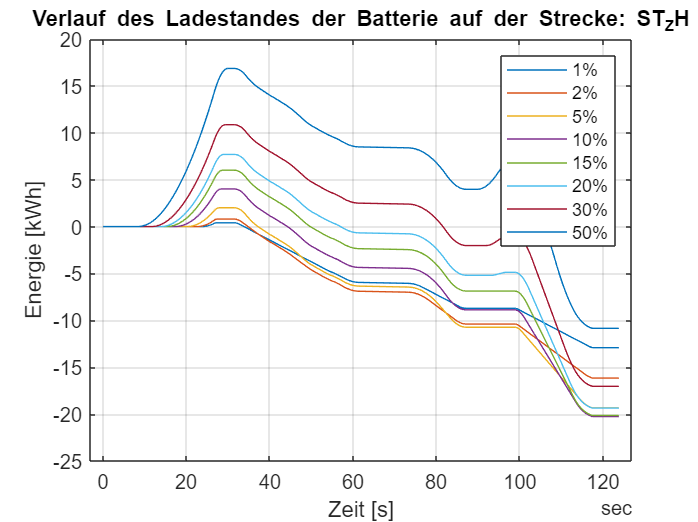

grid()

% Weiterverarbeitung:
load('BatterieTabelleDoppeltRecharging');
CRset = CRset(:); EBatCont = EBatCont(:); EBatPeak = EBatPeak(:); inters = inters(:); PBatCont = PBatCont(:); PBatPeak = PBatPeak(:);
%BD.(Str.id) = table(CRset.', EBatCont.', EBatPeak.', inters.', PBatCont.', PBatPeak.');
BDRecharging.(Str.id).BatTable = table(CRset, EBatCont, EBatPeak, inters, PBatCont, PBatPeak);
BDRecharging.(Str.id).CompData = CompData;
BDRecharging.(Str.id).EBatContReach = EBatContReach;
BDRecharging.(Str.id).EBatContReachTOT = EBatContReachTOT;
BDRecharging.(Str.id).EBatPeakReach = EBatPeakReach;
BDRecharging.(Str.id).EBatPeakReachTOT = EBatPeakReachTOT;
BDRecharging.(Str.id).PPeak = PPeak;
save('BatterieTabelleDoppeltRecharging', 'BDRecharging');

